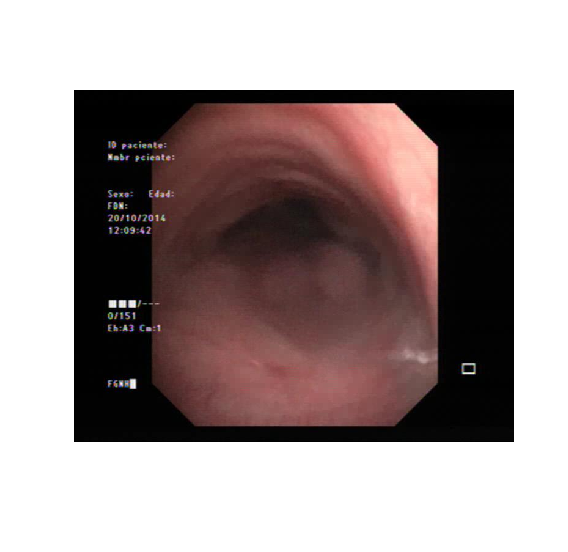

% cd frames\sick1\

% frame = imread('676.jpg');
% frame = imread('112.jpg');
frame = imread('250.jpg');
imshow(frame);

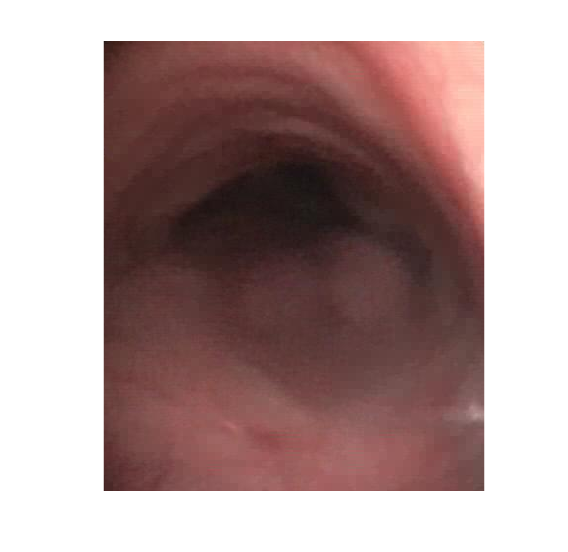


% //////// PREPROCESSING \\\\\\\\\\
% ------- Image Cropping ----------
frameCropped = imcrop(frame,[168,54,387,458]);
imshow(frameCropped);

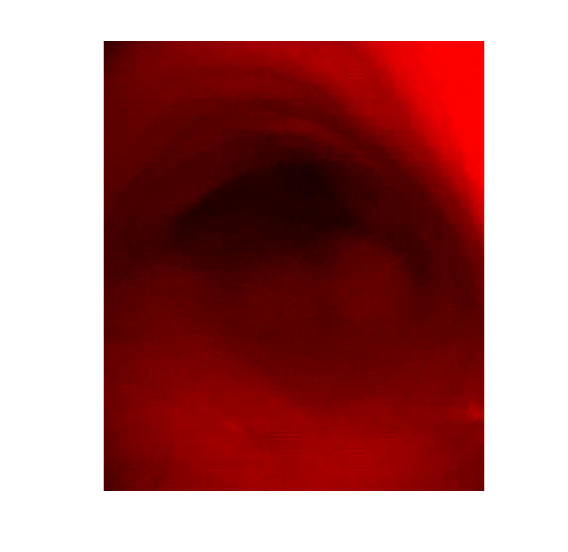

% ---------------------------------

% //////// BEST FEATURES \\\\\\\\\\
% ----------- Redness -------------
frameRChannel = frameCropped(:,:,1);
% Create an all black channel.
allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
% Create a color version of the Red Channel
frameRed = cat(3, frameRChannel, allBlack, allBlack);
% Print red channel
imshow(frameRed);

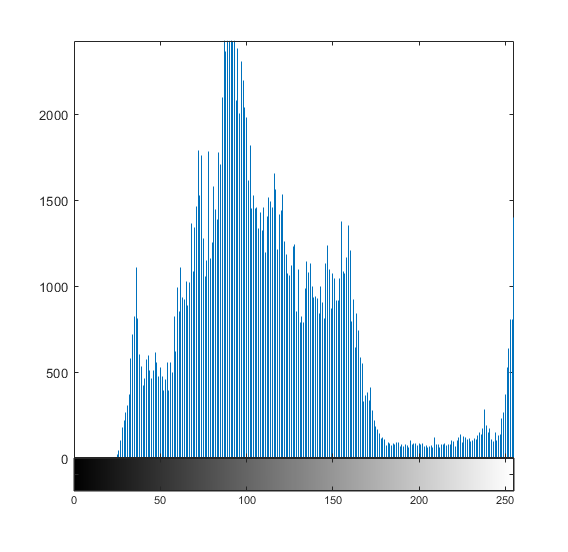

imhist(frameRChannel);

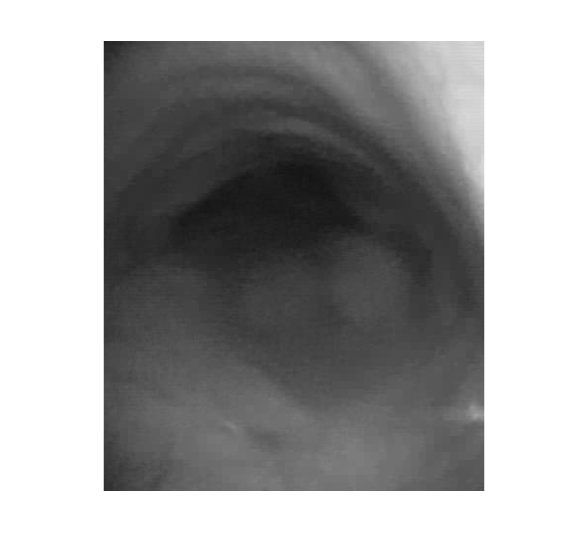


% ----------- Grayness ------------
frameGray = rgb2gray(frameCropped);
imshow(frameGray);

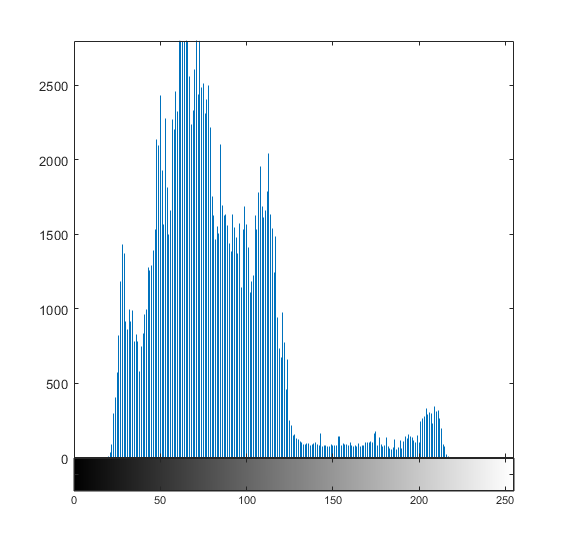

imhist(frameGray);

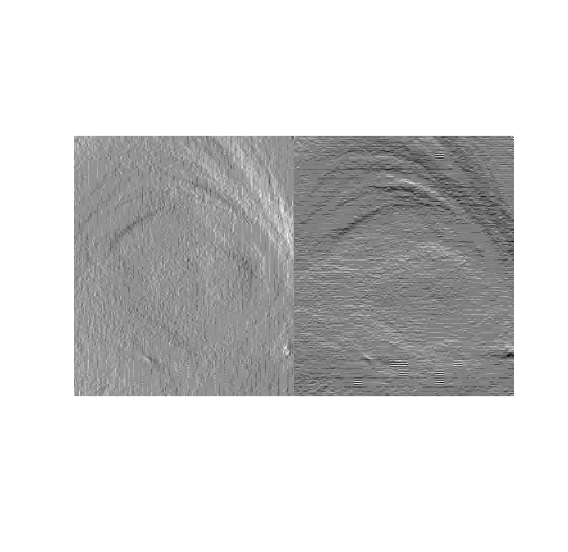

% ---------------------------------

% ----------- Gradient  -----------
[Gx, Gy] = imgradientxy(frameRChannel);
imshowpair(Gx,Gy,'montage')

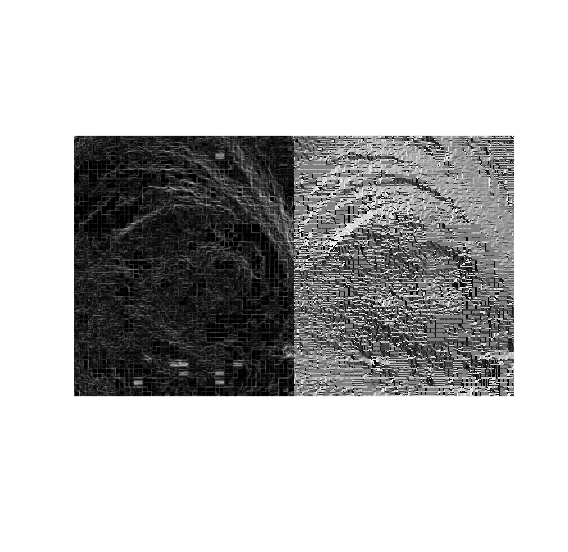

[Gmag,Gdir] = imgradient(Gx,Gy);
imshowpair(Gmag,Gdir,'montage')

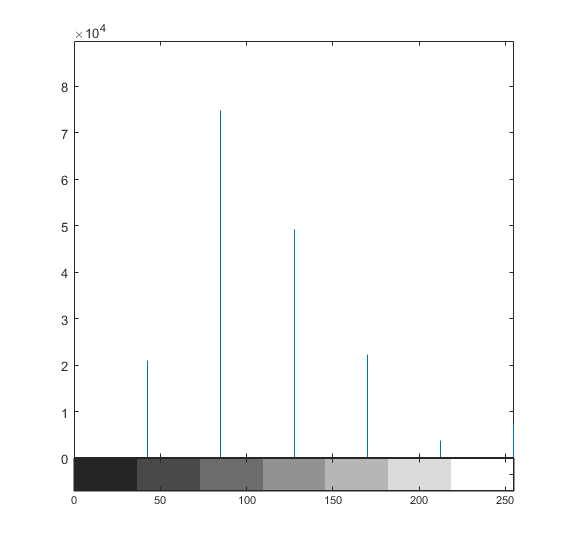

% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////
% \\\\\\\\\\\\\\\|/////////////////

% ///////// SEGMENTATION \\\\\\\\\\
% --------- Binarization ----------

% Image histogram with 6 bins
imhist(frameRChannel,7);

[counts,binLocations] = imhist(frameRChannel,6);
[dist,ix] = max(diff(counts))

dist =        49190

ix =      2

if ix == 1
    ix = 2
end
binThresh = ceil(abs((binLocations(ix + 1) + binLocations(ix))) / 2) 

binThresh =     77

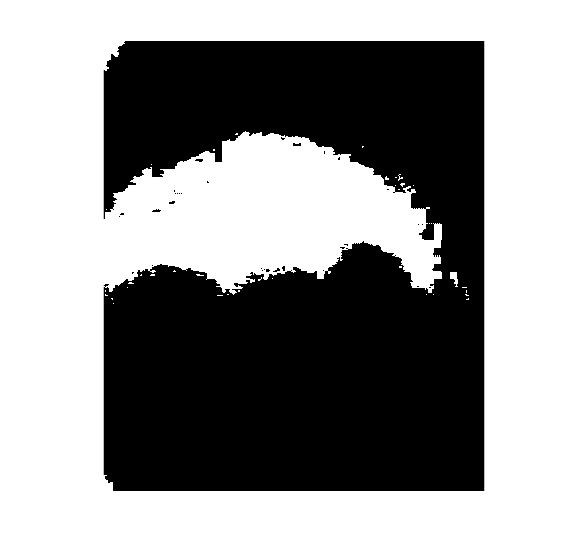


% Manual binaritzation
binFrameManual = frameRChannel < binThresh;

% Otsu binarization
level = graythresh(frameRChannel);
binFrameOtsu = imbinarize(frameRChannel,level);

% Adaptive binarization
binFrameAdaptive = imbinarize(frameRChannel,"adaptive", ...
    "ForegroundPolarity","bright","Sensitivity",0.66);

% Image Printing
imshow(binFrameManual);

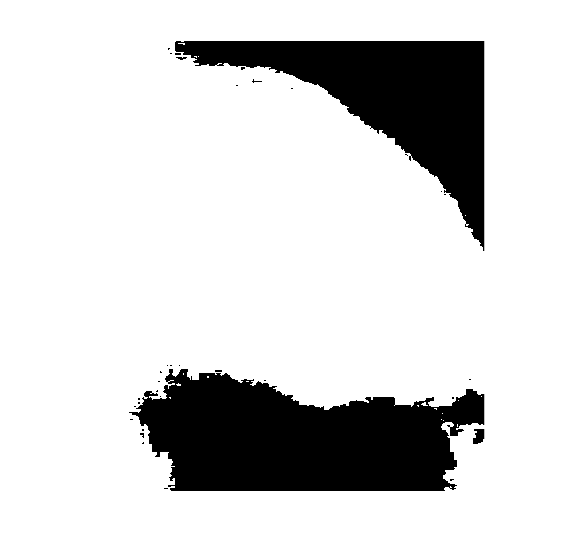

imshow(~binFrameOtsu);

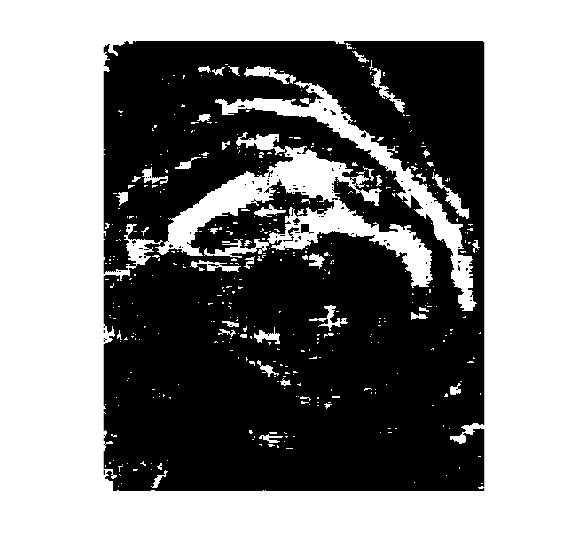

imshow(~binFrameAdaptive);

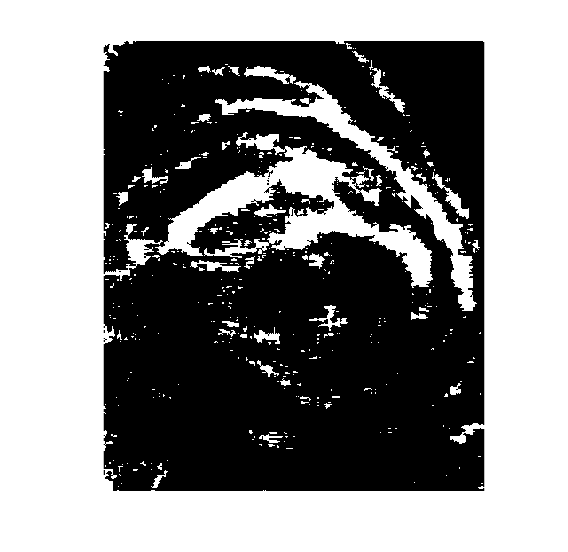

% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////

% //////// POSTPROCESSING \\\\\\\\\\
% -------- Filling holes ----------
filledFrame = imfill(~binFrameAdaptive,8,'holes');
imshow(filledFrame);

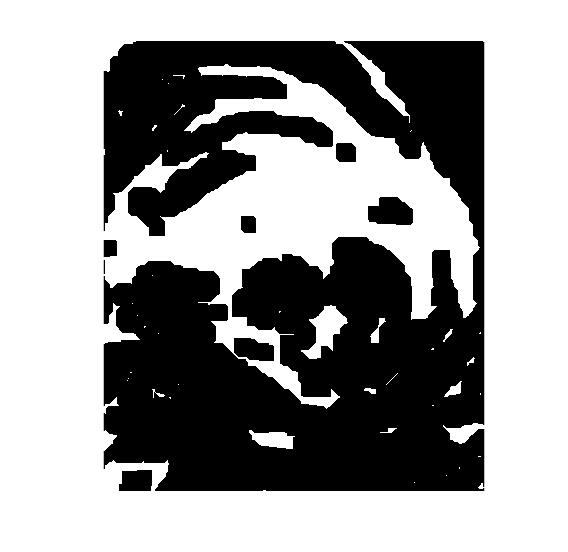

% ---------------------------------

% ---------- Closing gaps ---------
% With disks
% SE = strel('disk',15,8);
% closedFrame = imclose(filledFrame,SE);
% imshow(closedFrame); % Circle closed
% closedFilledFrame = imfill(closedFrame,8,'holes');
% imshow(closedFilledFrame);

% With lines
positiveSlope = strel('line',15,45);
negativeSlope = strel('line',15,-45);
horizontal = strel('line',15,0);
vertical = strel('line',15,90);
closedFrame=imclose(filledFrame,positiveSlope);
closedFrame=imclose(closedFrame,negativeSlope);
closedFrame=imclose(closedFrame,horizontal);
closedFrame=imclose(closedFrame,vertical);
imshow(closedFrame);

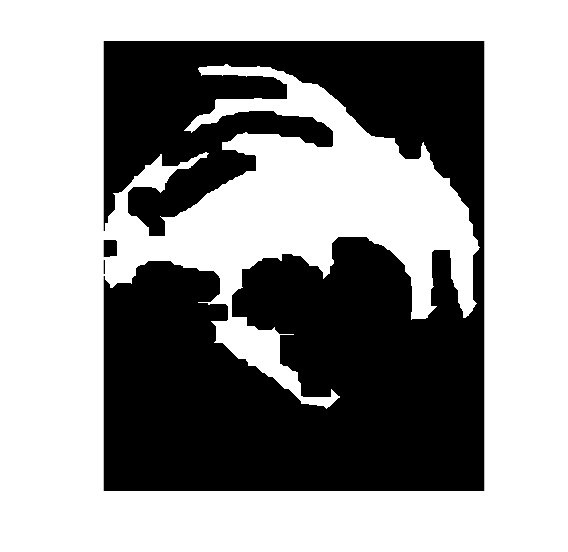

closedFilledFrame = imfill(closedFrame,8,'holes');
% ---------------------------------

% -- Removing small Conn. Comp. ---
props = regionprops(closedFilledFrame, 'Area');
allAreas = [props.Area];
cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)/2));
imshow(cleanedFrame);

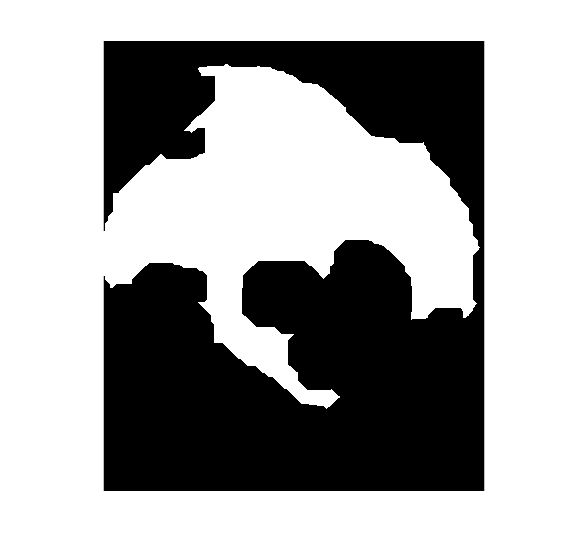

% ---- Extracting largest Blobs ---
% blobFrame = ExtractNLargestBlobs(cleanedFrame, 1);
% imshow(blobFrame);
positiveSlope = strel('line',25,45);
negativeSlope = strel('line',25,-45);
horizontal = strel('line',25,0);
vertical = strel('line',25,90);
closeBlobFrame=imclose(cleanedFrame,positiveSlope);
closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
closeBlobFrame=imclose(closeBlobFrame,horizontal);
closeBlobFrame=imclose(closeBlobFrame,vertical);
closeBlobFrame = imfill(closeBlobFrame,8,'holes');
imshow(closeBlobFrame);

% ---------------------------------
% ---------------------------------

% ----- Threading the needle ------
% ---------- Convex hull ----------
% unionFrame = bwconvhull(blobFrame, 'Union');
% imshow(unionFrame);
% ---------------------------------
% -------- Active Countour --------
%numberOfIterations = 100;
%bw = activecontour(frameRChannel, unionFrame, numberOfIterations, 'edge');
%imshow(bw);
% ---------------------------------
% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////

% Getting the area
bwarea(closeBlobFrame)

ans =                   61308.75

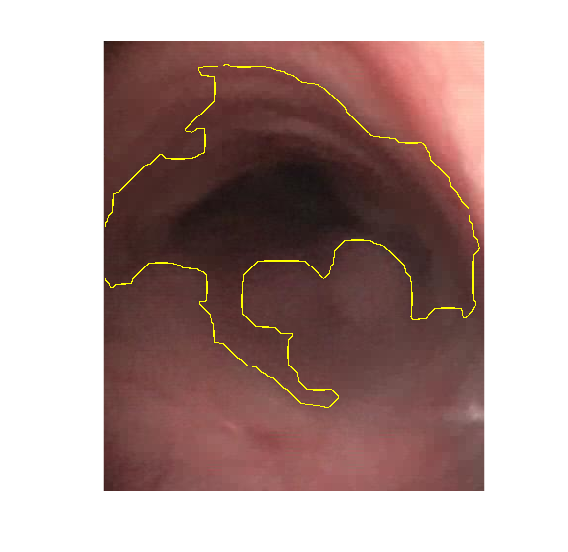

edgeDetected = edge(closeBlobFrame,"canny");
B = imoverlay(frameCropped,edgeDetected,'yellow');
imshow(B);

% cd ..\..\

function binaryImage = ExtractNLargestBlobs(binaryImage, numberToExtract)
try
  % Get all the blob properties.  Can only pass in originalImage in version R2008a and later.
  [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
  blobMeasurements = regionprops(labeledImage, 'area');
  % Get all the areas
  allAreas = [blobMeasurements.Area];
  if numberToExtract > 0
    % For positive numbers, sort in order of largest to smallest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'descend');
  elseif numberToExtract < 0
    % For negative numbers, sort in order of smallest to largest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'ascend');
    % Need to negate numberToExtract so we can use it in sortIndexes later.
    numberToExtract = -numberToExtract;
  else
    % numberToExtract = 0.  Shouldn't happen.  Return no blobs.
    binaryImage = false(size(binaryImage));
    return;
  end
  % Extract the "numberToExtract" largest blob(a)s using ismember().
  biggestBlob = ismember(labeledImage, sortIndexes(1:numberToExtract));
  % Convert from integer labeled image into binary (logical) image.
  binaryImage = biggestBlob > 0;
catch ME
  errorMessage = sprintf('Error in function ExtractNLargestBlobs().\n\nError Message:\n%s', ME.message);
  fprintf(1, '%s\n', errorMessage);
  uiwait(warndlg(errorMessage));
end
end